% load datasets
netflix_data = readtable('netflix.csv');

hulu_data = readtable('hulu.csv');

prime_data = readtable('prime.csv');

## Normal Distribtion of Age Rating

t = tiledlayout(3,2);
title(t,'Dot Plots and Normal Distributions per Feature');

% 1. AGE RATING
% dot plot
netflixAge = netflix_data{:,3};
huluAge = hulu_data{:,3};
primeAge = prime_data{:,3};
nexttile;
hold on
scatter(netflixAge,ones(size(netflixAge))*0.002,'r.');
scatter(huluAge,ones(size(huluAge))*0.001,'g.');
scatter(primeAge,zeros(size(primeAge)),'b.');

% compute means (mu) and standard deviations (sigma)
[netflixAgeMu,netflixAgeSigma] = normfit(netflixAge(~isnan(netflixAge)));
[huluAgeMu,huluAgeSigma] = normfit(huluAge(~isnan(huluAge)));
[primeAgeMu,primeAgeSigma] = normfit(primeAge(~isnan(primeAge)));
% plot normal distributions
netflixAgeX = linspace(netflixAgeMu-3*netflixAgeSigma,netflixAgeMu+3*netflixAgeSigma,100);
plot(netflixAgeX,normpdf(netflixAgeX,netflixAgeMu,netflixAgeSigma),'r','LineWidth',2);
huluAgeX = linspace(huluAgeMu-3*huluAgeSigma,huluAgeMu+3*huluAgeSigma,100);
plot(huluAgeX,normpdf(huluAgeX,huluAgeMu,huluAgeSigma),'g','LineWidth',2);
primeAgeX = linspace(primeAgeMu-3*primeAgeSigma,primeAgeMu+3*primeAgeSigma,100);
plot(primeAgeX,normpdf(primeAgeX,primeAgeMu,primeAgeSigma),'b','LineWidth',2);
xlabel('Age Rating');
ylabel('Probability Density');
title('Distribution of Age Ratings');
hold off


## Normal Distribution of IMDb Rating

% 2. IMDb RATING
% dot plot
netflixImdb = netflix_data{:,4};
huluImdb = hulu_data{:,4};
primeImdb = prime_data{:,4};
nexttile;
hold on
scatter(netflixImdb,ones(size(netflixImdb))*0.01,'r.');
scatter(huluImdb,ones(size(huluImdb))*0.02,'g.');
scatter(primeImdb,zeros(size(primeImdb)),'b.');

% compute means (mu) and standard deviations (sigma)
[netflixImdbMu,netflixImdbSigma] = normfit(netflixImdb(~isnan(netflixImdb)));
[huluImdbMu,huluImdbSigma] = normfit(huluImdb(~isnan(huluImdb)));
[primeImdbMu,primeImdbSigma] = normfit(primeImdb(~isnan(primeImdb)));
% plot normal distributions
netflixImdbX = linspace(netflixImdbMu-3*netflixImdbSigma,netflixImdbMu+3*netflixImdbSigma,100);
plot(netflixImdbX,normpdf(netflixImdbX,netflixImdbMu,netflixImdbSigma),'r','LineWidth',2);
huluImdbX = linspace(huluImdbMu-3*huluImdbSigma,huluImdbMu+3*huluImdbSigma,100);
plot(huluImdbX,normpdf(huluImdbX,huluImdbMu,huluImdbSigma),'g','LineWidth',2);
primeImdbX = linspace(primeImdbMu-3*primeImdbSigma,primeImdbMu+3*primeImdbSigma,100);
plot(primeImdbX,normpdf(primeImdbX,primeImdbMu,primeImdbSigma),'b','LineWidth',2);
xlabel('IMDb Rating');
ylabel('Probability Density');
title('Distribution of IMDb Ratings');
hold off


## Normal Distribution of Rotten Tomatoes

% 3. ROTTEN TOMATOES SCORE
% dot plot
netflixTomatoes = netflix_data{:,5};
huluTomatoes = hulu_data{:,5};
primeTomatoes = prime_data{:,5};
nexttile;
hold on
scatter(netflixTomatoes,ones(size(netflixTomatoes))*0.03,'r.');
scatter(huluTomatoes,ones(size(huluTomatoes))*0.06,'g.');
scatter(primeTomatoes,zeros(size(primeTomatoes)),'b.');

% compute means (mu) and standard deviations (sigma)
[netflixTomatoesMu,netflixTomatoesSigma] = normfit(netflixTomatoes(~isnan(netflixTomatoes)));
[huluTomatoesMu,huluTomatoesSigma] = normfit(huluTomatoes(~isnan(huluTomatoes)));
[primeTomatoesMu,primeTomatoesSigma] = normfit(primeTomatoes(~isnan(primeTomatoes)));
% plot normal distributions
netflixTomatoesX = linspace(netflixTomatoesMu-3*netflixTomatoesSigma,netflixTomatoesMu+3*netflixTomatoesSigma,100);
plot(netflixTomatoesX,normpdf(netflixTomatoesX,netflixTomatoesMu,netflixTomatoesSigma),'r','LineWidth',2);
huluTomatoesX = linspace(huluTomatoesMu-3*huluTomatoesSigma,huluTomatoesMu+3*huluTomatoesSigma,100);
plot(huluTomatoesX,normpdf(huluTomatoesX,huluTomatoesMu,huluTomatoesSigma),'g','LineWidth',2);
primeTomatoesX = linspace(primeTomatoesMu-3*primeTomatoesSigma,primeTomatoesMu+3*primeTomatoesSigma,100);
plot(primeTomatoesX,normpdf(primeTomatoesX,primeTomatoesMu,primeTomatoesSigma),'b','LineWidth',2);
xlabel('Rotten Tomatoes Score');
ylabel('Probability Density');
title('Distribution of Rotten Tomatoes Scores');
hold off


## Normal Distribution of Year

% 4. YEAR
% dot plot
netflixYear = netflix_data{:,2};
huluYear = hulu_data{:,2};
primeYear = prime_data{:,2};
nexttile;
hold on
%scatter(netflixYear,zeros(size(netflixYear)),'r.');
scatter(netflixYear,ones(size(netflixYear))*0.002,'r.');
scatter(huluYear,ones(size(huluYear))*0.001,'g.');
scatter(primeYear,zeros(size(primeYear)),'b.');

% compute means (mu) and standard deviations (sigma)
[netflixYearMu,netflixYearSigma] = normfit(netflixYear(~isnan(netflixYear)));
[huluYearMu,huluYearSigma] = normfit(huluYear(~isnan(huluYear)));
[primeYearMu,primeYearSigma] = normfit(primeYear(~isnan(primeYear)));
% plot normal distributions
netflixYearX = linspace(netflixYearMu-3*netflixYearSigma,netflixYearMu+3*netflixYearSigma,100);
plot(netflixYearX,normpdf(netflixYearX,netflixYearMu,netflixYearSigma),'r','LineWidth',2);
huluYearX = linspace(huluYearMu-3*huluYearSigma,huluYearMu+3*huluYearSigma,100);
plot(huluYearX,normpdf(huluYearX,huluYearMu,huluYearSigma),'g','LineWidth',2);
primeYearX = linspace(primeYearMu-3*primeYearSigma,primeYearMu+3*primeYearSigma,100);
plot(primeYearX,normpdf(primeYearX,primeYearMu,primeYearSigma),'b','LineWidth',2);
xlabel('Year');
ylabel('Probability Density');
title('Distribution of Years');
hold off


## Normal Distribution of Runtime

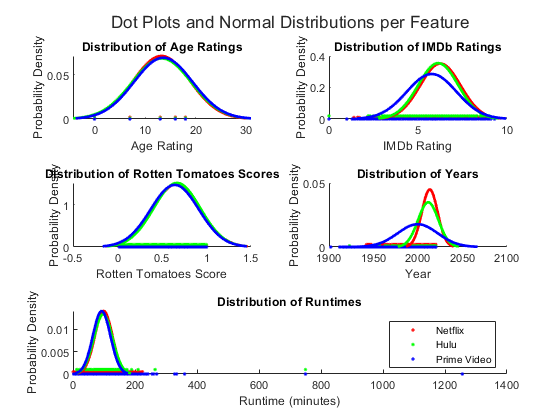

% 5. RUNTIME
% dot plot
netflixRuntime = netflix_data{:,10};
huluRuntime = hulu_data{:,10};
primeRuntime = prime_data{:,10};
nexttile(5,[1 2]);
hold on
scatter(netflixRuntime,ones(size(netflixRuntime))*0.0005,'r.');
scatter(huluRuntime,ones(size(huluRuntime))*0.001,'g.');
scatter(primeRuntime,zeros(size(primeRuntime)),'b.');

% compute means (mu) and standard deviations (sigma)
[netflixRuntimeMu,netflixRuntimeSigma] = normfit(netflixRuntime(~isnan(netflixRuntime)));
[huluRuntimeMu,huluRuntimeSigma] = normfit(huluRuntime(~isnan(huluRuntime)));
[primeRuntimeMu,primeRuntimeSigma] = normfit(primeRuntime(~isnan(primeRuntime)));
% plot normal distributions
netflixRuntimeX = linspace(netflixRuntimeMu-3*netflixRuntimeSigma,netflixRuntimeMu+3*netflixRuntimeSigma,100);
plot(netflixRuntimeX,normpdf(netflixRuntimeX,netflixRuntimeMu,netflixRuntimeSigma),'r','LineWidth',2);
huluRuntimeX = linspace(huluRuntimeMu-3*huluRuntimeSigma,huluRuntimeMu+3*huluRuntimeSigma,100);
plot(huluRuntimeX,normpdf(huluRuntimeX,huluRuntimeMu,huluRuntimeSigma),'g','LineWidth',2);
primeRuntimeX = linspace(primeRuntimeMu-3*primeRuntimeSigma,primeRuntimeMu+3*primeRuntimeSigma,100);
plot(primeRuntimeX,normpdf(primeRuntimeX,primeRuntimeMu,primeRuntimeSigma),'b','LineWidth',2);
legend('Netflix','Hulu','Prime Video');
xlabel('Runtime (minutes)');
ylabel('Probability Density');
title('Distribution of Runtimes');
%xlim([0 300]);
hold off